# Tarea 3

## Control todo nada con histéresis y PD de un sistema inestable

Se dispone de una tabla con valores de 2 Polos (uno de ellos inestable), ganancia y tiempo de establecimiento 2% para cada alumno, se pide:

**Diseñar un controlado PD de tiempo continuo de la forma  **$C(s) = K_c(s+a)$** mediante sisotool de Matlab de forma que el cero cancele el polo estable de la planta y ajustando la ganancia **$K_c
$** para obtener el tiempo de establecimiento deseado**

p1=1;
p2=-2;
K=5;
G=zpk([],[p1 p2],K)


G =
 
       5
  -----------
  (s-1) (s+2)
 
Continuous-time zero/pole/gain model.



%sisotool(G);

Se diseña el PD los requisitos de diseño.

C = zpk(-2,[], 0.45988)


C =
 
  0.45988 (s+2)
 
Continuous-time zero/pole/gain model.



**Simular en el diagrama adjunto cuya configuracion se cambia con la variable lineal y mostrar el error, dibujar al plano de fases, la acción de control y determinar el error de régimen.**

Kc= C.K % ganancia

Kc = 0.4599

a= -C.Z{1} % cero del controlador con signo invertido

a = 2

M=1 % ganancia rele

M = 1

T=0.1 % histeresis

T = 0.1000

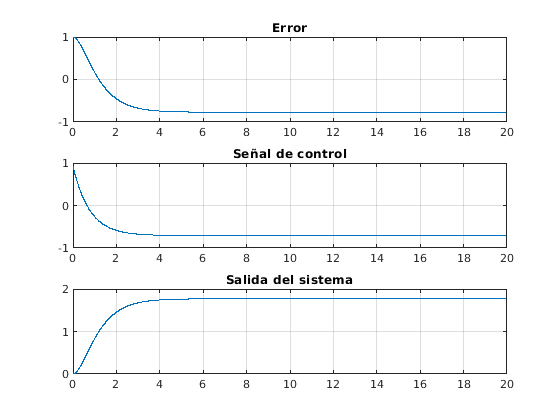

lineal=1; % simula control lineal
sim('bang_bang_hist_DI_PD')
subplot(3,1,1);
plot(tout,yout(:,1)) % error
grid on
title('Error')
subplot(3,1,2);
plot(tout,yout(:,2)) % señal de control
grid on
title('Señal de control')
subplot(3,1,3);
plot(tout,yout(:,4)) % salida del sistema
grid on
title('Salida del sistema')

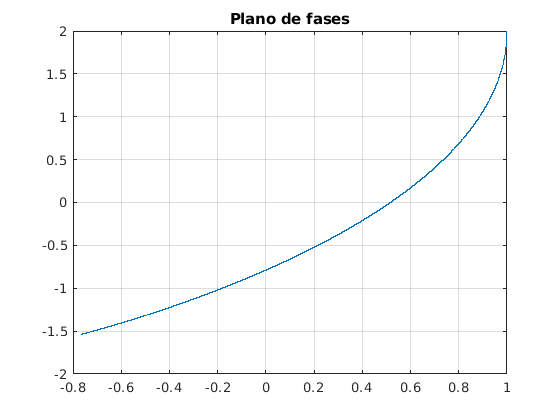


figure
plot(yout(:,1),yout(:,3)) % plano de fases: eje x error, eje y derivada del error
grid on
title('Plano de fases')

El error de regimen es de $-0.7696$.

**Con un ancho de histéresis **$T$** cien veces menos que la ganancia total **$Kc·K$** simular y dibujar lo mismo que con el controlador lineal pero cambiando las líneas.**

M=Kc % ganancia rele = +-ganancia Kc

M = 0.4599

T=K*Kc/100 % 100 veces menos que la ganancia total

T = 0.0230

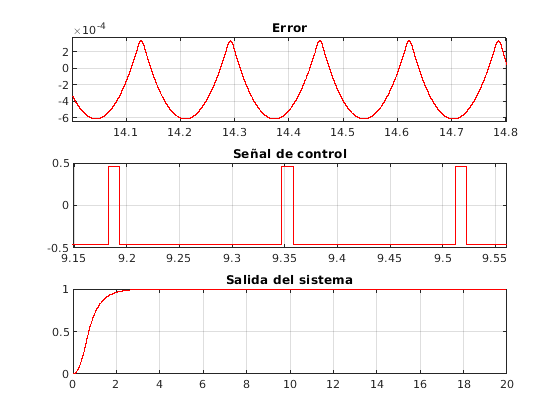

lineal=0; % simula no lineal
sim('bang_bang_hist_DI_PD')
figure
subplot(3,1,1);
plot(tout,yout(:,1), 'Color', 'r') % error
grid on
title('Error')
xlim([14.002 14.802])
ylim([-0.00065 0.00038])
subplot(3,1,2);
plot(tout,yout(:,2), 'Color', 'r') % señal de control
grid on
title('Señal de control')
xlim([9.149 9.561])
ylim([-0.50 0.50])
subplot(3,1,3);
plot(tout,yout(:,4), 'Color', 'r') % salida del sistema
grid on
title('Salida del sistema')


figure
plot(yout(:,1),yout(:,3), 'Color', 'r') % plano de fases: eje x error, eje y derivada del error
grid on
title('Plano de fases')


A partir de la introducción del control no lineal, se observa que el error de regimen se transformo en una señal periódica, cuyos valores oscilan entre $3.293e-4$ y $ -6.128e-4$. El tiempo de establecimiento del sistema disminuyó.

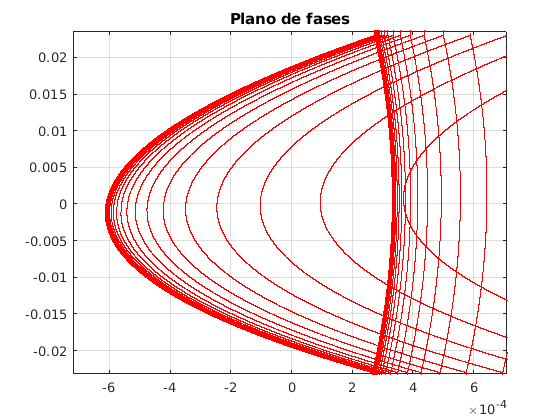

xlim([-0.00072 0.00071])
ylim([-0.0232 0.0236])

Existe un ciclo límite con amplitud $0.023$. La cota de valor absoluto del error es de $9.421e-4$

La frecuencia de conmutación de la señal de control es de $6 Hz$

fcon = 1/(9.347-9.182)

fcon = 6.0606

**Aumentar el ancho de histéresis y analizar como evolucionan el error máximo, el tiempo de establecimiento y la frecuencia de conmutación.**

M=Kc % ganancia rele = +-ganancia Kc

M = 0.4599

T=K*Kc/25 % 25 veces menos que la ganancia total

T = 0.0920

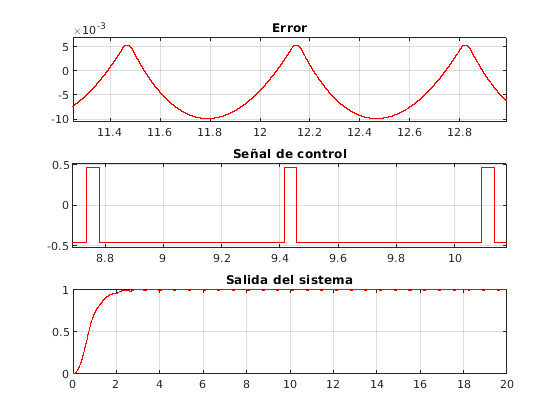

lineal=0; % simula no lineal
sim('bang_bang_hist_DI_PD')
figure
subplot(3,1,1);
plot(tout,yout(:,1), 'Color', 'r') % error
grid on
title('Error')
xlim([11.25 12.99])
ylim([-0.0106 0.0070])
subplot(3,1,2);
plot(tout,yout(:,2), 'Color', 'r') % señal de control
grid on
title('Señal de control')
xlim([8.69 10.18])
ylim([-0.53 0.52])
subplot(3,1,3);
plot(tout,yout(:,4), 'Color', 'r') % salida del sistema
grid on
title('Salida del sistema')

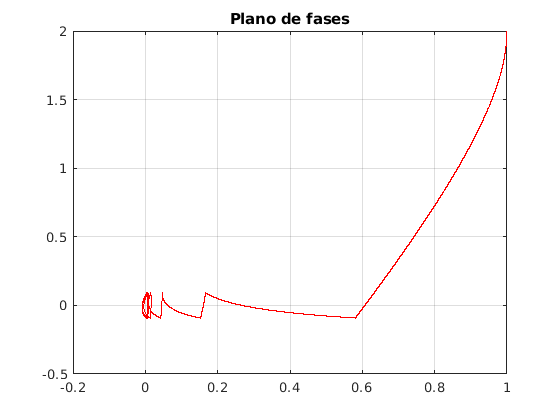


figure
plot(yout(:,1),yout(:,3), 'Color', 'r') % plano de fases: eje x error, eje y derivada del error
grid on
title('Plano de fases')

El error máximo crece a $5.53e-3$ y además, la frecuencia de conmutación de la accion de control es de $1.47 Hz$

fcon = 1/(9.415-8.737) 

fcon = 1.4749

M=Kc % ganancia rele = +-ganancia Kc

M = 0.4599

T=K*Kc/10 % 10 veces menos que la ganancia total

T = 0.2299

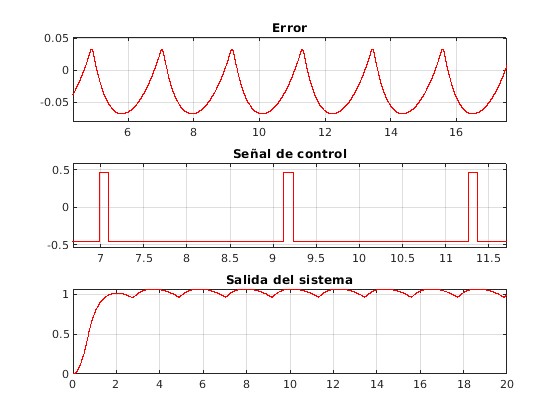

lineal=0; % simula no lineal
sim('bang_bang_hist_DI_PD')
figure
subplot(3,1,1);
plot(tout,yout(:,1), 'Color', 'r') % error
grid on
title('Error')
xlim([4.32 17.54])
ylim([-0.081 0.052])
subplot(3,1,2);
plot(tout,yout(:,2), 'Color', 'r') % señal de control
grid on
title('Señal de control')
xlim([6.68 11.71])
ylim([-0.54 0.59])
subplot(3,1,3);
plot(tout,yout(:,4), 'Color', 'r') % salida del sistema
grid on
title('Salida del sistema')

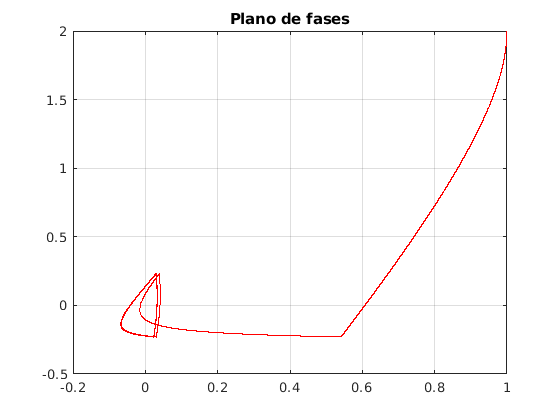


figure
plot(yout(:,1),yout(:,3), 'Color', 'r') % plano de fases: eje x error, eje y derivada del error
grid on
title('Plano de fases')

El error máximo crece a $3.262e-2
$ y además, la frecuencia de conmutación de la accion de control es de $0.46 Hz$

fcon = 1/(9.124-6.985) 

fcon = 0.4675

En conclusión, al aumentar el ancho de histéresis el error máximo sube y la frecuencia de conmutación baja.

**Subir el ancho de histéresis a la ganancia total ¿Qué sucede con la estabilidad? Explorar la causa viendo la acción de control.**

M=Kc % ganancia rele = +-ganancia Kc

M = 0.4599

T=K*Kc

T = 2.2994

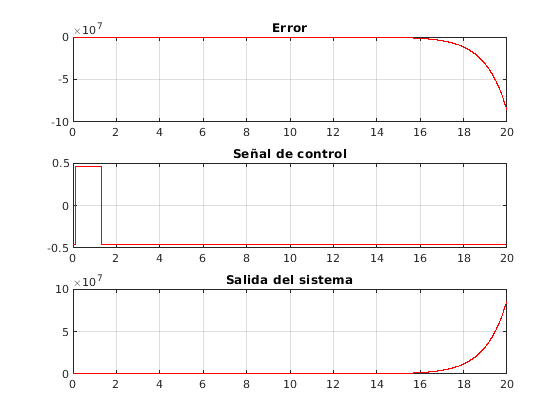

lineal=0; % simula no lineal
sim('bang_bang_hist_DI_PD')
figure
subplot(3,1,1);
plot(tout,yout(:,1), 'Color', 'r') % error
grid on
title('Error')
subplot(3,1,2);
plot(tout,yout(:,2), 'Color', 'r') % señal de control
grid on
title('Señal de control')
subplot(3,1,3);
plot(tout,yout(:,4), 'Color', 'r') % salida del sistema
grid on
title('Salida del sistema')

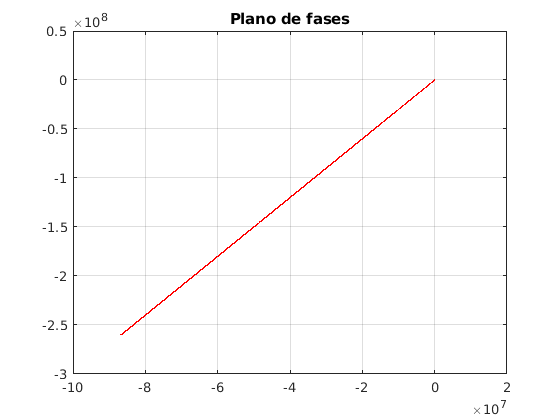


figure
plot(yout(:,1),yout(:,3), 'Color', 'r') % plano de fases: eje x error, eje y derivada del error
grid on
title('Plano de fases')

El sistema se vuelve inestable debido a que la acción de control conmuta una sola vez. El error se acumula infinitamente.